close all
clear all
l = 1; % Länge des Fadens in m
r = 0.1; % Radius der Kugel in m

[t,u] = ode45(@pendel, [0 10], [pi/4 0])

t =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0001
    0.0001
    0.0002
    0.0004


u =     0.7854         0
    0.7854   -0.0001
    0.7854   -0.0001
    0.7854   -0.0002
    0.7854   -0.0002
    0.7854   -0.0005
    0.7854   -0.0007
    0.7854   -0.0010
    0.7854   -0.0012
    0.7854   -0.0025


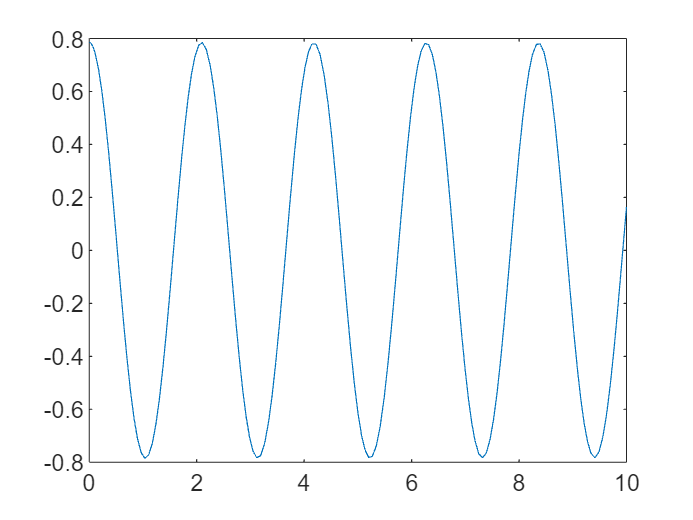

plot(t,u(:,1))


u(1,1)

ans = 0.7854

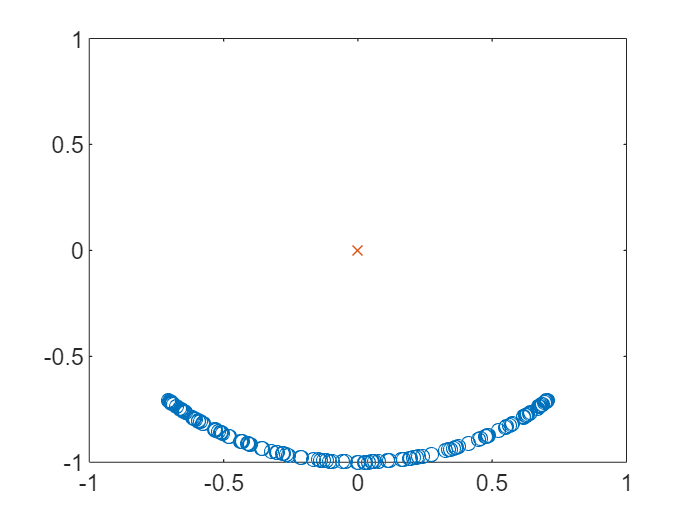


xkor = l * sin(u(:,1));
ykor = -l * cos(u(:,1));

plot(xkor, ykor, 'o')
hold on
plot(0,0,'x')
axis([-1 1 -1 1])
hold off


% Exporting to a .csv
data = [l*ones(size(t)), r*ones(size(t)), xkor, ykor];

writematrix(data, 'coordinates.csv')